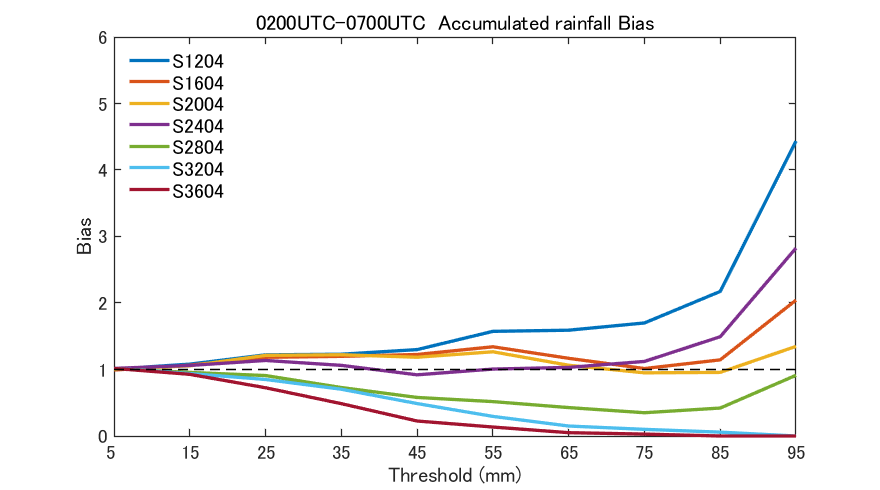


exp={'e10';'e47';'e46';'e41';'e42';'e45';'e02'};   exptext='_hrls';                %!!!remember to change the lengend below
lexp={'-';'-';'-';'-';'-';'-';'-';'-'};
cexp=[0.3 0.3 0.3; 
    0.6 0.6 0.7;
    0.9 0.7 0.7;
    0.95 0.6 0.6 ; 
    0.85 0.4 0.1; 
    0.75 0.35 0.05; 
    0.5 0.25 0.05];
expnam={'S1204';'S1604';'S2004';'S2404';'S2804';'S3204';'S3604'};

nexp=size(exp,1);


plotvar = [

    1.0061    1.0807    1.2205    1.2297    1.2992    1.5737    1.5909    1.7000    2.1739    4.4348
    0.9922    1.0657    1.1833    1.1978    1.2254    1.3417    1.1682    1.0143    1.1449    2.0435
    1.0061    1.0548    1.2128    1.2217    1.1844    1.2665    1.0636    0.9500    0.9565    1.3478
    1.0165    1.0608    1.1359    1.0622    0.9201    1.0063    1.0318    1.1214    1.4928    2.8261
    1.0122    0.9562    0.9090    0.7289    0.5799    0.5172    0.4273    0.3500    0.4203    0.9130
    1.0174    0.9392    0.8500    0.7033    0.4877    0.2947    0.1500    0.1000    0.0580         0
    1.0165    0.9273    0.7256    0.4864    0.2254    0.1348    0.0500    0.0286         0         0 ];

tresh=5:10:95;
%tresh=[5 10 20 30 50 70 100 130 160 190 220 260 300];
sth=2;  acch=5;   s_sth=num2str(sth,'%2.2d'); s_edh=num2str(sth+acch,'%2.2d');
nt=length(tresh);
s_plot='Bias';

figure('position',[-900 200 880 490])
for i=1:nexp
plot(1:nt,plotvar(i,:),'Linestyle',lexp{i},'LineWidth',2.5); hold on
end
if strcmp(s_plot,'Bias')==1
line([1 nt],[1 1],'color','k','linewidth',1.2,'LineStyle','--')
end
set(gca,'XLim',[1 nt],'YLim',[0 6],'XTick',1:nt,'XTickLabel',tresh,'fontsize',14,'LineWidth',1)
xlabel('Threshold (mm)','fontsize',15);   ylabel(s_plot,'fontsize',15);
%hl=legend(expnam,'Location','BestOutside');
hl=legend(expnam,'Location','Northwest');
set(hl,'fontsize',15,'box','off');
%tit=[s_sth,'z-',s_edh,'z accumulation rainfall ',s_plot,' (area',num2str(araid),')'];
tit=[s_sth,'00UTC-',s_edh,'00UTC  Accumulated rainfall ',s_plot];
title(tit,'fontsize',17)
outfile=[s_plot,'_',s_sth,s_edh,exptext,'_area',num2str(4)];
 set(gcf,'PaperPositionMode','auto');  
 print('-dpdf','-bestfit',[outfile,'.pdf'])
 print('-dpng',[outfile,'.png'])

 system(['convert -trim -density 600 ',outfile,'.pdf ',outfile,'.png']);

無効なパラメーターです - -density 


 %system(['rm ',[outfile,'.pdf']]);


